## Initialize the FMCW Radar Computations

clear;
simulator = Simulator_revB();
kristen_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
david_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
% file_path = "20MHz.json";
 file_path = "20MHz_USRP.json";
% file_path = "100MHz.json";
% file_path = "1GHz.json";
% file_path = "4GHz.json";
simulator.load_params_from_JSON(david_path + file_path);

%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_realistic_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_radar_parameters();

Chirp Parameters
	 Start Frequency: 		 1.50 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 199.86 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 2027.17 m/s
	 Velocity Resolution 		 31.67 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 
CFAR Detection Region
	 Range Detection Region 		 44.967 m to 427.186 m
	 Velocity Detection Region 		 -1742.098 m/s to 1773.772 m/s


### Initialize the target

simulator.load_target_realistic(100,-5);

### Initialize the Victim and Simulation Parameters

%specify the number of frames and chirps to compute
frames_to_compute = 10;

%specify whether or not to record a move of the range-doppler plot
record_movie = false;
simulator.Victim.Radar_Signal_Processor.configure_movie_capture(frames_to_compute,record_movie);

%pre-compute the victim's chirps
simulator.Victim.precompute_radar_chirps();

%initialize the attacker
%initialize the attacker parameters
simulator.Attacker.initialize_attacker(...
                        simulator.Victim.FMCW_sampling_rate_Hz * 1e-6,...
                        simulator.Victim.StartFrequency_GHz,...
                        simulator.Victim.Chirp_Tx_Bandwidth_MHz);

%initialize the sensing subsystem's debugger
simulator.Attacker.Subsystem_spectrum_sensing.initialize_debugger(0,simulator.Victim,frames_to_compute);
%set to change 1 to zero to disable

%specify the type of emulation ("target", 
        % "velocity spoof - noisy", 
        % "velocity spoof - similar velocity",
        % "range spoof - similar slope")

attack_type = "velocity spoof - similar velocity";
%attack_type = "velocity spoof - similar velocity,range spoof - similar slope ";
%initialize the attacker
simulator.Attacker.Subsystem_attacking.set_attack_mode(attack_type);

%if it is desired to specify a specific attack location
% simulator.Attacker.Subsystem_attacking.set_desired_attack_location(75,7);

## Save the victim chirp to a file

%save the full chirp as a binary file
path = "/home/david/Documents/MATLAB_generated/MATLAB_full_chirps/chirp_full.bin";
simulator.save_to_file(simulator.Victim.chirp,path);

### Plot Tx Chirp to confirm correctness

%plot the chirp signal
t = 0:simulator.Victim.FMCW_sampling_period_s:...
    simulator.Victim.ChirpCycleTime_us * 1e-6 - ...
    simulator.Victim.FMCW_sampling_period_s;
%plot(t,real(data),t,imag(data))
%spectrogram(data,64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')

## Run the Simulation

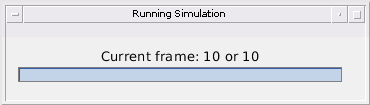

%run the simulation (without an attacker for now)
simulator.run_simulation_with_attack(frames_to_compute,true);

## Verify C++ computations

### Spectrogram Generation

#### Get key initialization parameters

%print key properties for spectrum subsystem
num_rows = size(simulator.Attacker.Subsystem_spectrum_sensing.reshaped_signal,2);
samples_per_sampling_window = simulator.Attacker.Subsystem_spectrum_sensing.spectogram_params.num_samples_per_sampling_window;
fft_size = simulator.Attacker.Subsystem_spectrum_sensing.spectogram_params.fft_size;
samp_freq = simulator.Attacker.FMCW_sample_rate_Msps * 1e6;

fprintf(" rows: %d \n samples per sampling window: %d \n fft size: %d \n samp freq: %d",...
    num_rows,samples_per_sampling_window,fft_size,samp_freq);

 rows: 986 
 samples per sampling window: 60 
 fft size: 32 
 samp freq: 2.953600e+07

#### Verify Hanning Window

%get the hanning window
path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_hanning_window.bin";
read_data = simulator.read_from_file(path,true,"float");

%compare with the computed hanning window
compare = all(abs(read_data - simulator.Attacker.Subsystem_spectrum_sensing.spectogram_params.window) < 1e-5);
if compare
    fprintf("Hanning window matches")
else
    fprintf("Hanning window doesn't match")
end

Hanning window matches

#### Reshaped and windowed Received Signal - save received signal to file

%print the number of received samples
received_samples = size(simulator.Attacker.Subsystem_spectrum_sensing.received_signal,2);
fprintf(" receieved_samples: %d\n",received_samples)

 receieved_samples: 59160


%save the full chirp as a binary file
path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/MATLAB_received_signal.bin";
simulator.save_to_file(simulator.Attacker.Subsystem_spectrum_sensing.received_signal.',path);

#### Reshape Received Signal - read and verify

%get the reshaped for fft signal
path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_reshaped_and_windowed_for_fft.bin";

read_data = simulator.read_from_file(path,true,"float");
read_data_reshaped = reshape(read_data,fft_size,num_rows);

%compare with the computed hanning window

compare = all(abs(read_data_reshaped - simulator.Attacker.Subsystem_spectrum_sensing.windowed_signal) < 1e-5);

if compare
    fprintf("Reshaped and windowed signal for fft matches")
else
    fprintf("Reshaped and windowed signal for fft doesn't match")
end

Reshaped and windowed signal for fft doesn't match

#### Computed FFT - read and verify

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_generated_spectrogram.bin";

read_data = simulator.read_from_file(path,false,"float");
read_data_reshaped = reshape(read_data,fft_size,num_rows);
tolerance = 1e-1; %spectrogram converted to dB
compare = all(abs(read_data_reshaped - simulator.Attacker.Subsystem_spectrum_sensing.generated_spectogram) < tolerance);

if compare
    fprintf("Generated spectrogram matches")
else
    fprintf("Generated spectrogram doesn't match")
end

Generated spectrogram doesn't match

#### Detected Times and Frequencies - read and verify

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_detected_frequencies.bin";

read_data = simulator.read_from_file(path,false,"float");

difference = max(abs(read_data - simulator.Attacker.Subsystem_spectrum_sensing.detected_frequencies.'));

Arrays have incompatible sizes for this operation.

Related documentation


out_string = sprintf("Detected frequencies: max difference = %f MHz",difference);
fprintf(out_string);

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_detected_times.bin";
read_data = simulator.read_from_file(path,false,"float");

difference = max(abs(read_data - simulator.Attacker.Subsystem_spectrum_sensing.detected_times.'));

out_string = sprintf("Detected times: max difference = %f us",difference);
fprintf(out_string);

#### Clusters - read and verify

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_computed_clusters.bin";
read_data = simulator.read_from_file(path,false,"int");
read_data = read_data(read_data ~= 0);

compare = all(read_data == simulator.Attacker.Subsystem_spectrum_sensing.idx);

if compare
    fprintf("Clusters match")
else
    fprintf("Clusters don't match")
end

#### Computed Linear Models

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_detected_slopes.bin";
read_data = simulator.read_from_file(path,false,"float");

tolerance = 1e-2;
difference = max(abs(read_data - simulator.Attacker.Subsystem_spectrum_sensing.detected_chirps(:,2)));

out_string = sprintf("Detected Slope: max difference = %0.3f MHz/us",difference);
fprintf(out_string);
path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_detected_intercepts.bin";
read_data = simulator.read_from_file(path,false,"float");

%add in the detected start time as USRP code doesn't have this
read_data = read_data + simulator.Attacker.Subsystem_spectrum_sensing.detection_start_time;

tolerance = 0.2; %tolerance is in us, low tolerance due to resolution of the floating point value

difference = max(abs(read_data - simulator.Attacker.Subsystem_spectrum_sensing.detected_chirps(:,1)));

out_string = sprintf("Detected Intercepts: max difference = %0.3f us",difference);
fprintf(out_string);

#### Captured Frames Array

path = "/home/david/Documents/MATLAB_generated/cpp_sensed_parameters/cpp_captured_frames.bin";
read_data = simulator.read_from_file(path,false,"float");
read_data = reshape(read_data,6,[]).'

% tolerance = 1e-2;
% difference = max(abs(read_data - simulator.Attacker.Subsystem_spectrum_sensing.detected_chirps(:,2)));
% 
% out_string = sprintf("Detected Slope: max difference = %0.3f MHz/us",difference);
% fprintf(out_string);